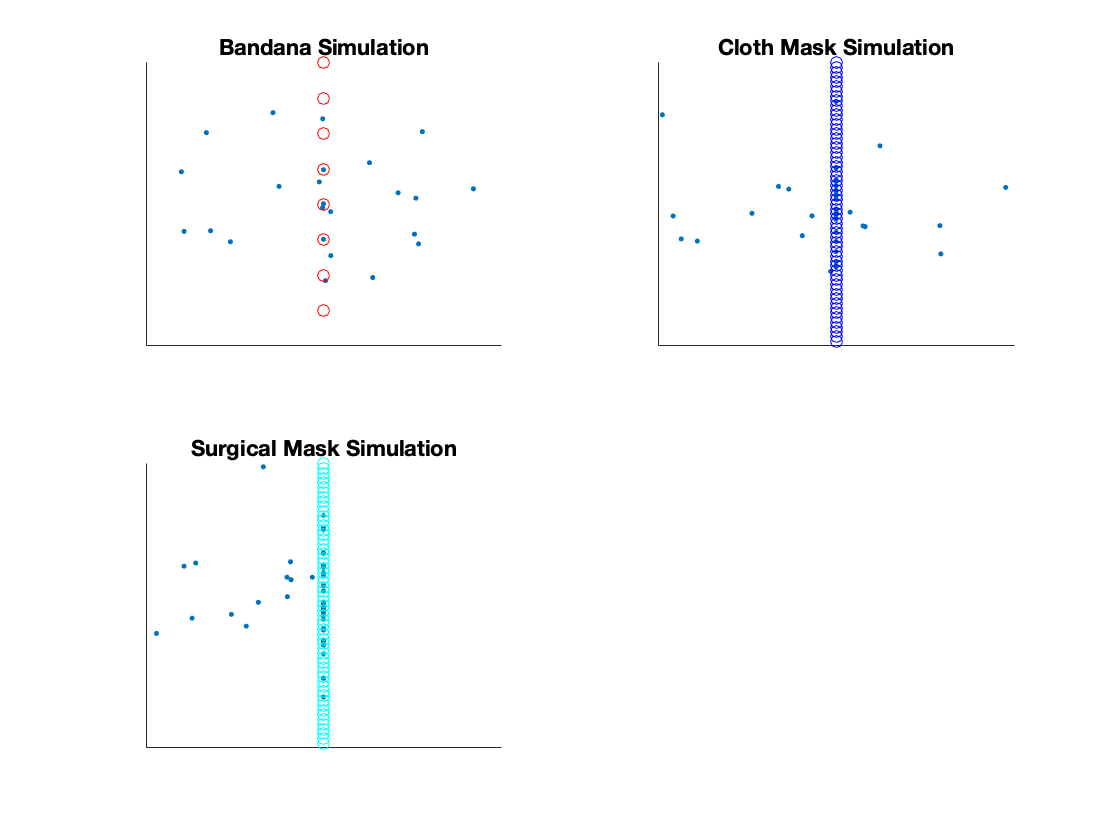

%Simulation for cloth, bandana, and surgical mask filtration efficiency

numCovidParticles = 50;                                             % initialize number of moving respiratory particles

%Covid particles pertaining to the bandana mask
covidParticlesPosBand = zeros(numCovidParticles,2);                     % initialize zeros array of respiratory particle positions
covidParticlesPosBand(:,2) = normrnd(0.5,0.15,1,numCovidParticles);     % assign random y value to respiratory particle positions
covidParticlesVelBand = rand(length(covidParticlesPosBand),2);              % initialize random velocity of repiratory particles

%Covid particles pertaining to the cloth mask
covidParticlesPosCloth = zeros(numCovidParticles,2);                     % initialize zeros array of respiratory particle positions
covidParticlesPosCloth(:,2) = normrnd(0.5,0.15,1,numCovidParticles);     % assign random y value to respiratory particle positions
covidParticlesVelCloth = rand(length(covidParticlesPosCloth),2);              % initialize random velocity of repiratory particles

%Covid particles pertaining to the surgical mask
covidParticlesPosSurg = zeros(numCovidParticles,2);                     % initialize zeros array of respiratory particle positions
covidParticlesPosSurg(:,2) = normrnd(0.5,0.15,1,numCovidParticles);     % assign random y value to respiratory particle positions
covidParticlesVelSurg = rand(length(covidParticlesPosSurg),2);              % initialize random velocity of repiratory particles

dt = 0.01;                                                          % initialize a small dt in order to be able to visually see timesteps
threadRadius = 0.005;                                                % initialize a small thread radius to interact with covid particles

numBandanaParticles = 8;                                % initialize number of bandana threads (determined by ratio to other masks as outlined in our research)
bandanaParticlesPos = zeros(numBandanaParticles,2);     % initialize zeros array of bandana thread positions
bandanaParticlesPos(:,1) = 0.5;                         % place bandana thread x value in the middle of experiment window

numClothParticles = 60;                             % Repeat initialization process for cloth mask threads
clothParticlesPos = zeros(numClothParticles,2);
clothParticlesPos(:,1) = 0.5;
                    
numSurgParticles = 60;                          % Repeat initialization process for the mechanical layer of surgical mask threads
surgParticlesPos = zeros(numClothParticles,2);
surgParticlesPos(:,1) = 0.5;


for i = 1:numBandanaParticles                   % Distribute bandana threads equally along a line in the experiment window
    distribution = 1 / numBandanaParticles;
    bandanaParticlesPos(i,2) = i * distribution;
end

for i = 1:numClothParticles                     % Distribute cloth threads equally along a line in the experiment window
    distribution = 1 / numClothParticles;
    clothParticlesPos(i,2) = i * distribution;
end

for i = 1:numSurgParticles                      % Distribute surgical mask threads equally along a line in the experiment window
    distribution = 1 / numSurgParticles;
    surgParticlesPos(i,2) = i * distribution;
end


for t = 1:200                                   % we chose a time length of 200 proficient to demonstrate our model
    for i = 1:numCovidParticles         % iterate through respiratory (covid-infected) particles
        covidParticlesPosBand(i,1) = covidParticlesPosBand(i,1) + covidParticlesVelBand(i,1)*dt;    % use equation 13b as derived in Simulation2: Penny Drop to update x position
        covidParticlesPosCloth(i,1) = covidParticlesPosCloth(i,1) + covidParticlesVelCloth(i,1)*dt;
        covidParticlesPosSurg(i,1) = covidParticlesPosSurg(i,1) + covidParticlesVelSurg(i,1)*dt;
    
        for p = 1:length(bandanaParticlesPos)    % if a covid particle comes into contact (overlaps) with a bandana thread, it "sticks", and make the velocity 0
            if sqrt((covidParticlesPosBand(i,1) - bandanaParticlesPos(p,1))^2 + (covidParticlesPosBand(i,2) - bandanaParticlesPos(p,2))^2) < threadRadius
                covidParticlesVelBand(i) = 0;
                covidParticlesPosBand(i,1) = 0.5;
            end
        end
        
        for j = 1:length(clothParticlesPos)        % if a covid particle comes into contact (overlaps) with a cloth thread, it "sticks", and make the velocity 0
            if sqrt((covidParticlesPosCloth(i,1) - clothParticlesPos(j,1))^2 + (covidParticlesPosCloth(i,2) - clothParticlesPos(j,2))^2) < threadRadius
                covidParticlesVelCloth(i) = 0;
                covidParticlesPosCloth(i,1) = 0.5;
            end
        end
        
        for w = 1:length(surgParticlesPos)          % if a covid particle comes into contact (overlaps) with a surgical mask thread, it "sticks", and make the velocity 0
            if sqrt((covidParticlesPosSurg(i,1) - surgParticlesPos(w,1))^2 + (covidParticlesPosSurg(i,2) - surgParticlesPos(w,2))^2) < threadRadius
                covidParticlesVelSurg(i) = 0;
                covidParticlesPosSurg(i,1) = 0.5;
            end
            
            if covidParticlesPosSurg(i,1) > 0.5     %surgical masks have an electrostatic layer that filters out 85% of particles
                randomAssignment = rand;            %this code here filters covid particles out if they interact with electrostatic layer
                if randomAssignment < 0.85
                    covidParticlesVelSurg(i) = 0;
                    covidParticlesPosSurg(i,1) = 0.5;
                end
            end
        end
    end
    
    tiledlayout('flow');
    nexttile;
    scatter(covidParticlesPosBand(:,1), covidParticlesPosBand(:,2), '.')        % graph bandana simulation
    hold on
    scatter(bandanaParticlesPos(:,1), bandanaParticlesPos(:,2), 'o', 'red')
    title("Bandana Simulation")
    xlim([0 1]);
    ylim([0 1]);
    set(gca,'XTick',[], 'YTick', [])
    hold off
    

    nexttile;
    scatter(covidParticlesPosCloth(:,1), covidParticlesPosCloth(:,2), '.')    % graph cloth mask simulation
    hold on
    scatter(clothParticlesPos(:,1), clothParticlesPos(:,2), 'o', 'blue')
    title("Cloth Mask Simulation")
    xlim([0 1]);
    ylim([0 1]);
    set(gca,'XTick',[], 'YTick', [])
    hold off
    
    nexttile;
    scatter(covidParticlesPosSurg(:,1), covidParticlesPosSurg(:,2), '.')    % graph surgical mask simulation
    hold on
    scatter(surgParticlesPos(:,1), surgParticlesPos(:,2), 'o', 'cyan')
    title("Surgical Mask Simulation")
    xlim([0 1]);
    ylim([0 1]);
    set(gca,'XTick',[], 'YTick', [])
    hold off

    pause(0.001)    % pause for visualization
  
end